## Cascaded tank system

clc;
clear;

global a1 a2 A g
a1 = 0.4% Valve output of tank 1

a1 = 0.4000

a2 = 0.3% Valve output of tank 2

a2 = 0.3000

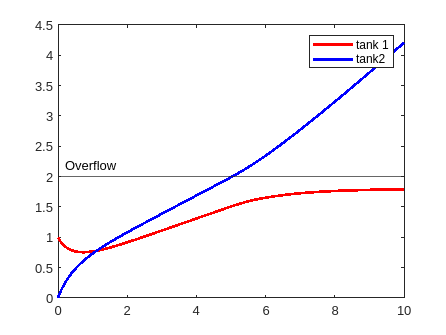

A = 1; % Area of tanks
g = 9.8; % Acceleration due to gravity

tspan = [0 10];
h0 = [1; 0];

[t,h] = ode45(@(t,h) tankeqn(t,h), tspan, h0);

plot(t,h(:,1),'r-',t,h(:,2),'b-','Linewidth',2); hold on;
yline(2)
text(0.2,2.2,sprintf('Overflow'))
legend('tank 1', 'tank2');

### Functions

function dh = tankeqn(t,h)
global a1 a2 A g
u = control(t);
h(1) = min(max(0,h(1)),2);
h(2) = min(max(0,h(2)),2);

% Series system
% dh1 = u - a1/A*sqrt(2*g*h(1));
% dh2 = a1/A*sqrt(2*g*h(1)) - a2/A*sqrt(2*g*h(2));

% Feedback system
dh1 = u - a1/A*sqrt(2*g*h(1)) + a2/A*sqrt(2*g*h(2));
dh2 = a1/A*sqrt(2*g*h(1)) - a2/A*sqrt(2*g*h(2));

dh = [dh1; dh2];
end

%% Control
function u = control(t)
u = abs(sin(t));
u=0.5;
end